# Example Two

Solve the following Ordinary Differential Equations System


$$\frac{dx}{dt} = x + 2y + z$$



$$\frac{dy}{dt} = 18
$$



$$\frac{dz}{dt} = -1
$$


With initial conditions $x(0) = y(0) = z(0) = 5$

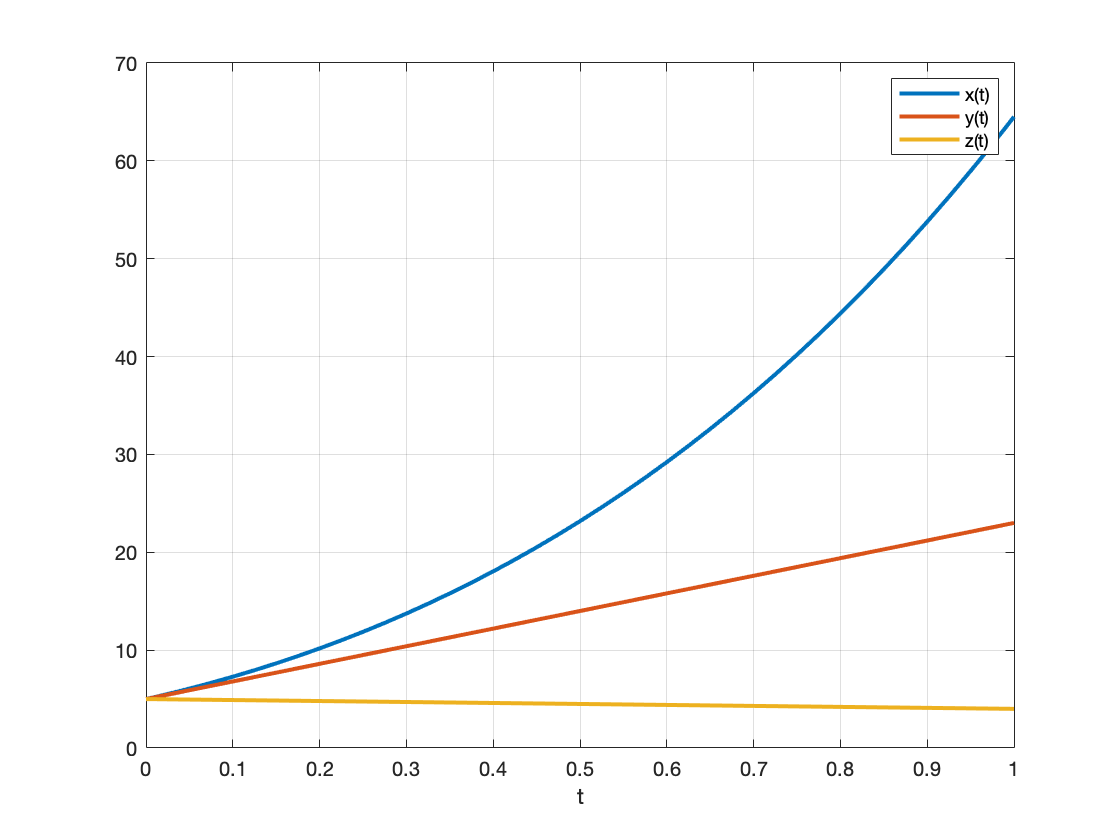

tRange = [0 1];
W0 = [5; 5; 5];
[tSol, WSol] = ode45(@mySystem,tRange,W0);

plot(tSol,WSol(:,1),'LineWidth',2)
hold on
plot(tSol,WSol(:,2),'LineWidth',2)
plot(tSol,WSol(:,3),'LineWidth',2)
hold off
grid on
xlabel('t')
legend('x(t)','y(t)','z(t)')

#### ODEs System Function

function dWdt = mySystem(t,W)
    x = W(1);
    y = W(2);
    z = W(3);
    
    dxdt = x + 2.*y + z;
    dydt = 18;
    dzdt = -1;
    
    dWdt = [dxdt;dydt;dzdt];
end